Загрузка данных

Рекорды женщин из 55 стран (строки) в 7 дистанциях бега :100м, 200м, 400м, 800м, 1500м, 3000м и марафон (столбцы)

load data.mat

Пробуем с выделением только одного фактора

Видим, что значение критического уровня значимости p < 0.05 => отвергается гипотеза о том, что число факторов равно одному

[Loadings,specificVar,T,stats] = factoran(data,1,'rotate','none');
stats

stats = struct with fields:
    loglike: -0.7588
        dfe: 14
      chisq: 38.0657
          p: 5.0776e-04


Пробуем с выделением двух факторов

Видим, что значение критического уровня значимости p = 0.6196 > 0.05 =>принимается гипотеза о том, что число факторов равно двум

[Loadings,specificVar,T,stats] = factoran(data,2,'rotate','none');
specificVar

specificVar =     0.0925
    0.1310
    0.3457
    0.0568
    0.5138
    0.3346
    0.3317


stats

stats = struct with fields:
    loglike: -0.1262
        dfe: 8
      chisq: 6.2470
          p: 0.6196


Loadings

Loadings =     0.8888   -0.3429
    0.8719   -0.3300
    0.8086    0.0220
    0.9289    0.2834
    0.6899    0.1012
    0.7970    0.1738
    0.8105    0.1065


Интерпретировать факторные нагрузки пока что затруднительно, воспользуемся функцией вращения факторов varimax

[LoadingsPM,specVarPM] = factoran(data,2,'rotate','varimax');
LoadingsPM

LoadingsPM =     0.4480    0.8407
    0.4436    0.8199
    0.6260    0.5122
    0.8880    0.3933
    0.5881    0.3747
    0.7165    0.3899
    0.6827    0.4496


Для сравнения еще воспользуемся функцией вращения факторов promax

[LoadingsPM,specVarPM, TPM, stats, F] = factoran(data,2,'rotate','promax');
LoadingsPM

LoadingsPM =     0.0057    0.9479
    0.0161    0.9190
    0.5501    0.2937
    1.0530   -0.1018
    0.6038    0.1104
    0.7903    0.0307
    0.6891    0.1508


Видим, что в данном случае более содержательную интерпретацию позволяет функция promax

Для упрощения анализа матрицы факторных нагрузок построим на ее основе новую матрицу, заменив в матрице факторных нагрузок все элементы больше 0.3 на 1, а меньше 0.3 на 0

Можно предположить, что первый фактор связан с выносливостью, а второй с быстротой

bLoadingsPM = LoadingsPM > 0.3

bLoadingsPM = 7×2 logical array
   0   1
   0   1
   1   0
   1   0
   1   0
   1   0
   1   0


Наглядно представим исходные данные в пространстве факторов, а также для интерпретации факторов построим совместный график значений скрытых факторов для наблюдаемых объектов, а также взаимосвязей исходных переменных с выделенными факторами

Видно, что результаты в дистанциях на 100м и 200м зависят сугубо от быстроты, в то время как результат в дистанции, напрмиер, на 3000м зависит преимущественно от выносливости

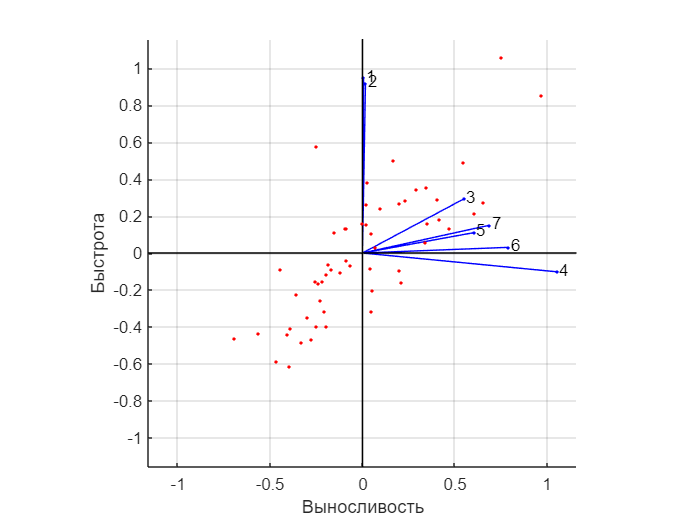

biplot(LoadingsPM,'scores',F,'varlabels',num2str((1:7)'))
xlabel('Выносливость')
ylabel('Быстрота')
axis square